DATA =load('carsmall.mat')

DATA = struct with fields:
           Model: [100×33 char]
          Origin: [100×7 char]
             MPG: [100×1 double]
       Cylinders: [100×1 double]
    Displacement: [100×1 double]
      Horsepower: [100×1 double]
          Weight: [100×1 double]
    Acceleration: [100×1 double]
      Model_Year: [100×1 double]
             Mfg: [100×13 char]


%Tehtävä 1. loaded database carsmall.mat and put on DATA variable
format long g
%Tehtävä 2. Formats the output to display full length 
digitsNew = digits(2)

digitsNew =      2


KWh =  round(Horsepower*0.745699872,2)

KWh =                      96.94
                    123.04
                    111.85
                    111.85
                     104.4
                    147.65
                    164.05
                    160.33
                    167.78
                    141.68


%Converting horsepower to kilowatt/H
Kg = round(Weight*0.45359237,2)

Kg =                    1589.39
                   1675.12
                   1558.54
                   1557.18
                   1564.44
                   1969.04
                   1974.94
                   1955.89
                   2007.15
                   1746.33


%pounds to kilos and rounded up by 2 decimal points
teho = round(KWh./Kg,2)

teho =                       0.06
                      0.07
                      0.07
                      0.07
                      0.07
                      0.07
                      0.08
                      0.08
                      0.08
                      0.08


% power from kwh divided by the mass
iskutilavuus = round(Displacement*16.38760, 2)

iskutilavuus =                    5030.99
                   5735.66
                   5211.26
                   4981.83
                   4949.06
                   7030.28
                   7439.97
                   7210.54
                   7456.36
                   6391.16


%engine displacement from  inch^3 to cm^3 conversion and 2 decimal round
%tehtävä 3.
plot(KWh, ".","MarkerEdgeColor", "r")
hold on
plot(Acceleration,".","MarkerEdgeColor", "b")
%displaying on plot both acceleration and kw/h with dots
hold off
%Tehtävä 4*
kmperLiter = round(282./MPG,2)

kmperLiter =                      15.67
                      18.8
                     15.67
                     17.63
                     16.59
                      18.8
                     20.14
                     20.14
                     20.14
                      18.8


%coonverting imperial mile per gallon to km per 100liter
Car = [DATA.Model];
%car names bracketed into a variable
%Tehtävä 5: Table and Matrix
T = table(Car,Acceleration,Cylinders,iskutilavuus,KWh,kmperLiter,Kg)

T = 100×7 table
                   Car                   Acceleration    Cylinders    iskutilavuus     KWh      kmperLiter      Kg   
    _________________________________    ____________    _________    ____________    ______    __________    _______

    chevrolet chevelle malibu                  12            8          5030.99        96.94      15.67       1589.39
    buick skylark 320                        11.5            8          5735.66       123.04       18.8       1675.12
    plymouth satellite                         11            8          5211.26       111.85      15.67       1558.54
    amc rebel sst                              12            8          4981.83       111.85      17.63       1557.18
    ford torino                      

DataMatrice = [Acceleration,Cylinders,iskutilavuus,KWh,kmperLiter,Kg]

DataMatrice =                         12                         8                   5030.99                     96.94                     15.67                   1589.39
                      11.5                         8                   5735.66                    123.04                      18.8                   1675.12
                        11                         8                   5211.26                    111.85                     15.67                   1558.54
                        12                         8                   4981.83                    111.85                     17.63                   1557.18
                      10.5                         8                   4949.06                     104.4                     16.59                   1564.44
                        10                         8                   7030.28                    147.65                      18.8                   1969.04
                         9                  

% Tehtävä 6: Created table for car data for regression data 
%curveFitter(KWh,Kg);
KwperKilo = Kg./KWh;
%Tehtävä 7: plotregression used for KwperKilo to acceleration
%plotregression(KwperKilo,Acceleration);
hold off
%Tehtävä 8:
%Creating regression model to figure out with multivariables

X = [KWh,Kg];
regressionModel = fitlm(X,Acceleration)

regressionModel = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                        Estimate                  SE                   tStat                 pValue       
                   ___________________    ___________________    _________________    ____________________

    (Intercept)       18.1862713122006      0.957644664648645     18.9906256292599    2.81218785566902e-34
    x1              -0.108881557871278     0.0139005151669181    -7.83291529585933    6.40204003068757e-12
    x2             0.00430682406877145    0.00128275397433125     3.35748253753551      0.0011286573800435


Number of observations: 99, Error degrees of freedom: 96
Root Mean Squared Error: 2.28
R-squared: 0.54,  Adjusted R-Squared: 0.53
F-statistic vs. constant model: 56.2, p-value = 6.82e-17

% y = 18.186 - 0,1088x1 + 0,0043x2

KWh(50,1) = 0;
%replaced 1 value from KWH to see difference in result
%no substantial difference
X = [KWh,Kg];
regressionModel2 = fitlm(X,Acceleration)

regressionModel2 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                        Estimate                 SE                   tStat                 pValue       
                   __________________    ___________________    _________________    ____________________

    (Intercept)       17.990571240727      0.941706586723466     19.1042215211881    1.78606176052926e-34
    x1             -0.107268847330107      0.012971905934926    -8.26932047366247    7.62378477290629e-13
    x2             0.0043159634111363    0.00122562073581963     3.52145103701268    0.000658579832767153


Number of observations: 99, Error degrees of freedom: 96
Root Mean Squared Error: 2.23
R-squared: 0.559,  Adjusted R-Squared: 0.55
F-statistic vs. constant model: 60.9, p-value = 8.37e-18

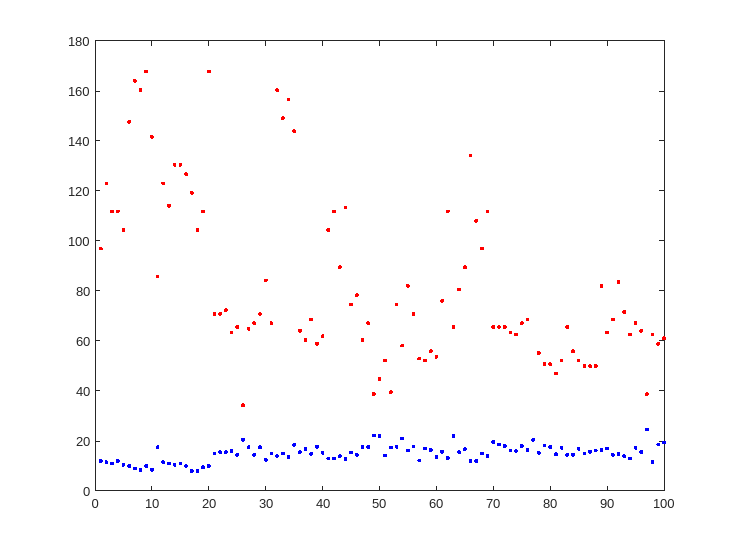



%Modeling a data set to predict car average fuel consumption
%Using cars Horsepower weight and engine dispalcement
KWh =  round(Horsepower*0.745699872,2);

%Tehtävä 10:
%Creating a plot with all the needed values 
% Y axis chosen to be the 100km/liter consumption and x axis the 
% other features of the car that affect the fuel consumption
% prediction displayed with fitlm and predict function

x = Kg;
z = KWh;
i = iskutilavuus;
y = kmperLiter;
hold off

mdl = fitlm(x,y)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                        Estimate                  SE                   tStat                 pValue       
                   __________________    ____________________    _________________    ____________________

    (Intercept)      -3.6939161965556       0.960414915948206    -3.84616704219826    0.000220931101974563
    x1             0.0128043844460046    0.000689987247879684     18.5574218731609    7.40640198771201e-33


Number of observations: 94, Error degrees of freedom: 92
Root Mean Squared Error: 2.42
R-squared: 0.789,  Adjusted R-Squared: 0.787
F-statistic vs. constant model: 344, p-value = 7.41e-33

ypred = predict(mdl,x);
plot(x,y,'.',x,ypred,'x')
hold on;
mdl = fitlm(z,y);
ypred = predict(mdl,z)

ypred =           15.6166352284229
          19.1520444795422
          17.6362885592347
          17.6362885592347
          16.6271391752945
          22.4856238538734
          24.7071070614733
           24.203209650969
          25.2123590349091
          21.6769497837898


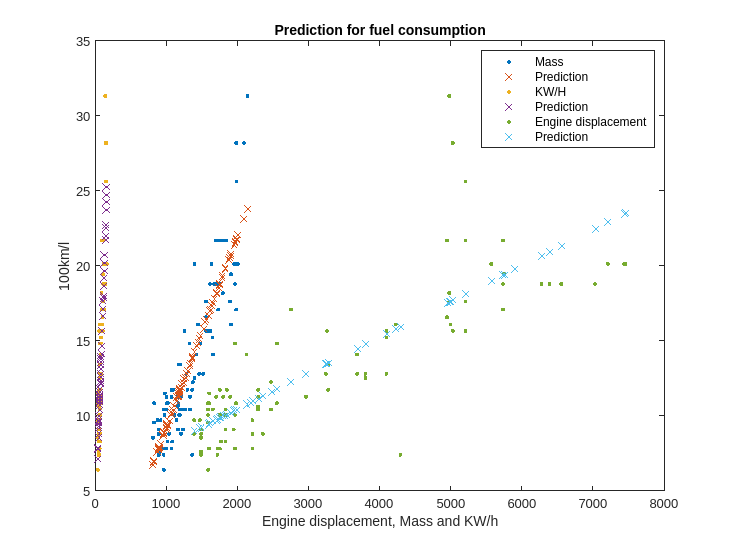

plot(z,y,'.',z,ypred,'x')
legend('Mass','Prediction','KW/H','Prediction');

mdl = fitlm(i,y);
ypred = predict(mdl,i);
plot(i,y,'.',i,ypred,'x');
legend('Mass','Prediction','KW/H','Prediction', "Engine displacement", "Prediction");
title("Prediction for fuel consumption")
clear ylabel
ylabel("100km/l")
xlabel("Engine displacement, Mass and KW/h")
hold off